# 3-1-a

## Signal Enhancement and Noise Reduction

In our example, the desired frequency response of the bandpass filter is only at the frequency ω0. Therefore, we need to design a bandpass filter that has unity gain at the frequency ω0, meaning |H(jω0)| = 1. The optimal choice for such a filter is a second-order amplifying filter with poles located at Re±jω0. To ensure stability, R should be chosen such that 0 < R < 1.

In time domain we have the desired equation as:

y(n) = -a1 * y(n-1) - a2 * y(n-2) + G * x(n)

and the impulse response would be:

h(n) = G * sin(ω0 * n + ω0), n = 0, 1, 2, ...

we define G to assure that |H(jw0|=1 so:

G = (1 - R)*(1 - 2*R*cos(2*ω0) + R^2) ^0.5

Finally, the squared magnitude of the transfer function is:

|H(jω)|^2 = G^2 / ((1 - 2*R*cos(ω - ω0) + R^2) * (1 - 2*R*cos(ω + ω0) + R^2))

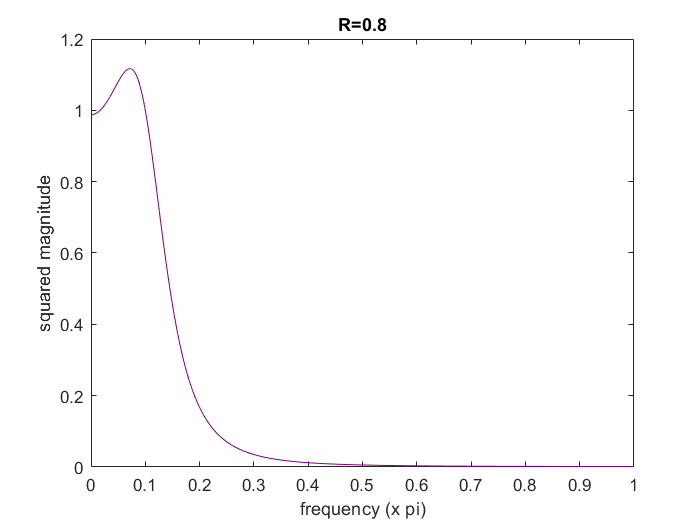

clear all;
clc;

%for R=0.8
w=linspace(0,pi,500);
w0=2*pi*500/10000; % frequency of the single tone signal
R=0.8;
G = (1 - R).*(1 - 2*R*cos(2*w0) + R^2)^0.5;
square_mag= G^2 ./ ((1 - 2*R*cos(w - w0) + R^2) .* (1 - 2*R*cos(w+w0) + R^2));

figure
plot(w/pi,square_mag,'color','[0.5 0 0.5]');
xlabel('frequency (x pi)');
ylabel('squared magnitude');
title('R=0.8');

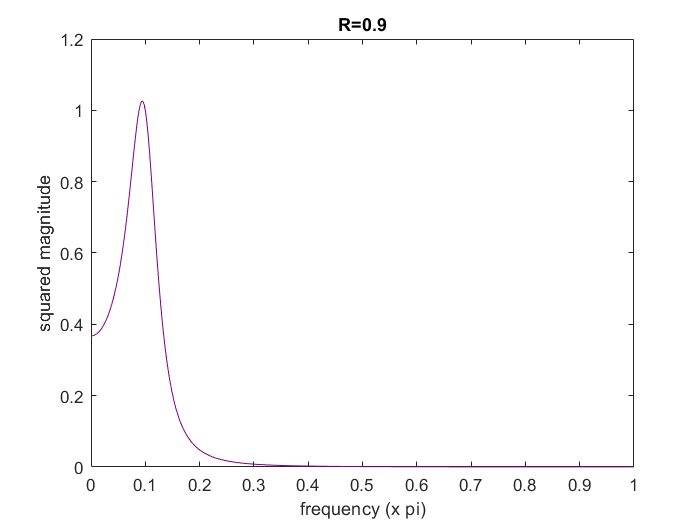



%for R=0.9
R=0.9;
G = (1 - R).*(1 - 2*R*cos(2*w0) + R^2)^0.5;
square_mag= G^2 ./ ((1 - 2*R*cos(w - w0) + R^2) .* (1 - 2*R*cos(w+w0) + R^2));
figure
plot(w/pi,square_mag,'color','[0.5 0 0.5]');
xlabel('frequency (x pi)');
ylabel('squared magnitude');
title('R=0.9');

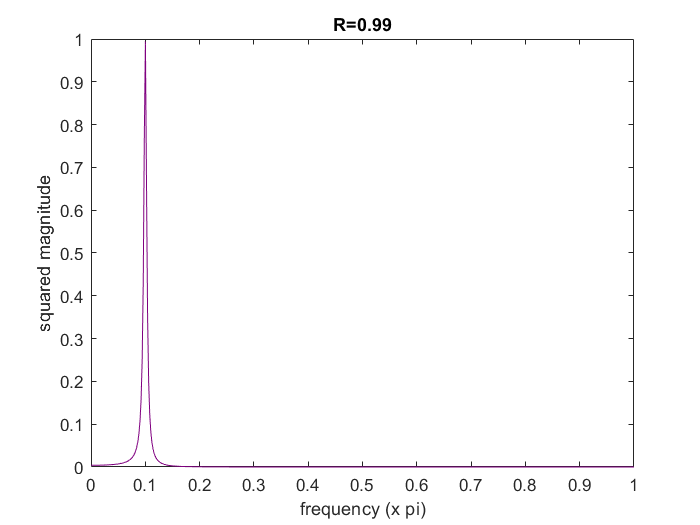



%for R=0.99
R=0.99;
G = (1 - R).*(1 - 2*R*cos(2*w0) + R^2)^0.5;
square_mag= G^2 ./ ((1 - 2*R*cos(w - w0) + R^2) .* (1 - 2*R*cos(w+w0) + R^2));
figure
plot(w/pi,square_mag,'color','[0.5 0 0.5]');
xlabel('frequency (x pi)');
ylabel('squared magnitude');
title('R=0.99');

# 3-1-b

In time domain we have:

y(n) = -a1 * y(n-1) - a2 * y(n-2) + G * x(n)

which a1= -2*R*cos(w0) and a2= R^2

the impulse response would be:

h(n) = (G / sin(ω0)) * R^n * sin(w0*n + w0) , n = 0, 1, 2, ...

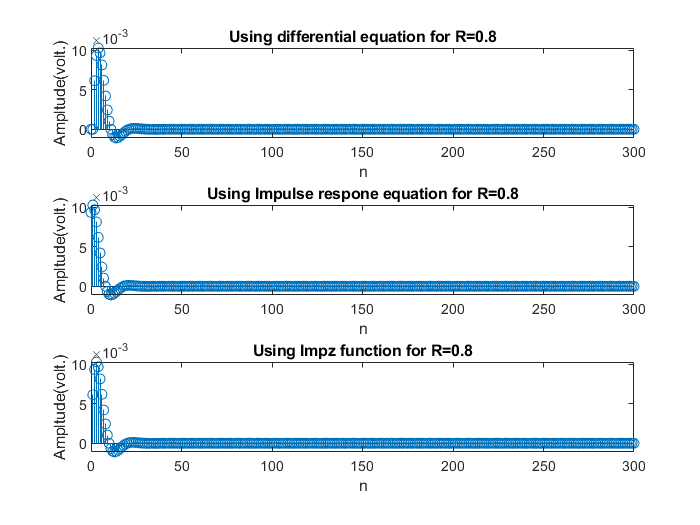


R=0.8;

a1= -2*R*cos(w0);
a2= R^2;

% Using differential Eq
N=1:301;
x=zeros(1,301);%Pulse input
x(3)=1;

y1=zeros(size(x));
for n = 3:length(x)
    y1(n) = -a1 * y1(n-1) - a2 * y1(n-2) + G * x(n);
end

% Using impulse response Eq

h1= (G / sin(w0)) .* R.^N .* sin(w0*N + w0);

% Using impz function
impz_1=impz([G],[1 a1 a2],300);


%Illustration
figure;
subplot(3,1,1)
stem(N-1,y1)
xlabel('n');
ylabel('Ampltude(volt.)');
title('Using differential equation for R=0.8');

subplot(3,1,2)
stem(N-1,h1)
xlabel('n');
ylabel('Ampltude(volt.)');
title('Using Impulse respone equation for R=0.8');

subplot(3,1,3)
stem(impz_1)
xlabel('n');
ylabel('Ampltude(volt.)');
title('Using Impz function for R=0.8');

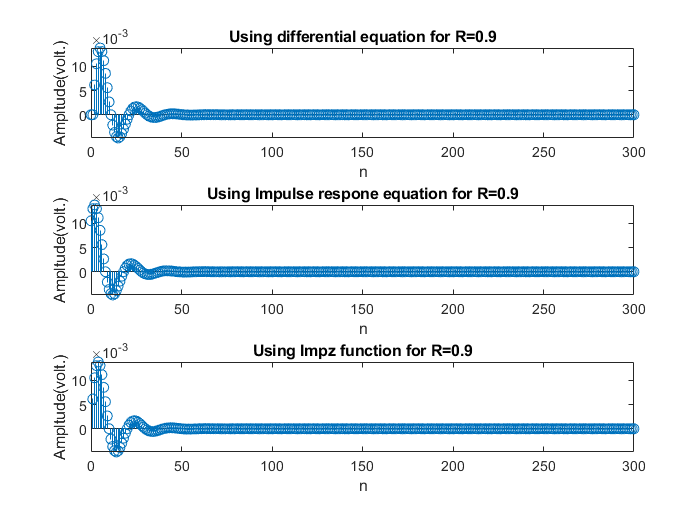



%-------------------------------------------------------------------------------------------
R=0.9;

a1= -2*R*cos(w0);
a2= R^2;

% Using differential Eq
N=1:301;
x=zeros(1,301);%Pulse input
x(3)=1;

y2=zeros(size(x));
for n = 3:length(x)
    y2(n) = -a1 * y2(n-1) - a2 * y2(n-2) + G * x(n);
end

% Using impulse response Eq

h2= (G / sin(w0)) .* R.^N .* sin(w0*N + w0);

% Using impz function
impz_2=impz([G],[1 a1 a2],300);


%Illustration
figure;
subplot(3,1,1)
stem(N-1,y2)
xlabel('n');
ylabel('Ampltude(volt.)');
title('Using differential equation for R=0.9');

subplot(3,1,2)
stem(N-1,h2)
xlabel('n');
ylabel('Ampltude(volt.)');
title('Using Impulse respone equation for R=0.9');

subplot(3,1,3)
stem(impz_2)
xlabel('n');
ylabel('Ampltude(volt.)');
title('Using Impz function for R=0.9');

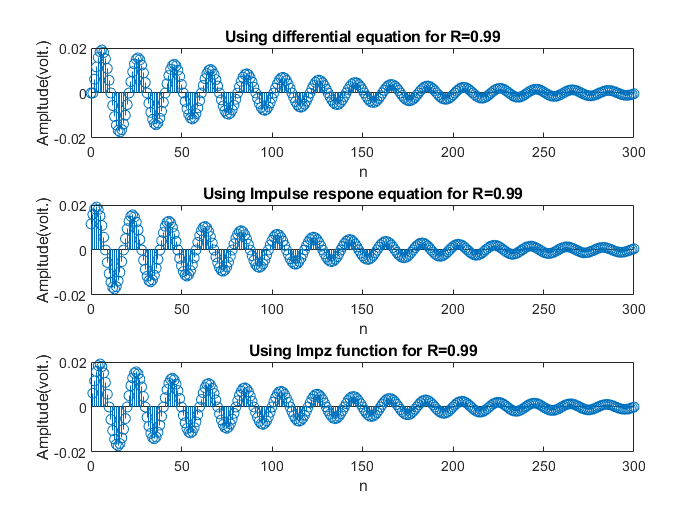


%-------------------------------------------------------------------------------------------
R=0.99;

a1= -2*R*cos(w0);
a2= R^2;

% Using differential Eq
N=1:301;
x=zeros(1,301);%Pulse input
x(3)=1;

y3=zeros(size(x));
for n = 3:length(x)
    y3(n) = -a1 * y3(n-1) - a2 * y3(n-2) + G * x(n);
end

% Using impulse response Eq

h3= (G / sin(w0)) .* R.^N .* sin(w0*N + w0);

% Using impz function
impz_3=impz([G],[1 a1 a2],300);


%Illustration
figure;
subplot(3,1,1)
stem(N-1,y3)
xlabel('n');
ylabel('Ampltude(volt.)');
title('Using differential equation for R=0.99');

subplot(3,1,2)
stem(N-1,h3)
xlabel('n');
ylabel('Ampltude(volt.)');
title('Using Impulse respone equation for R=0.99');

subplot(3,1,3)
stem(impz_3)
xlabel('n');
ylabel('Ampltude(volt.)');
title('Using Impz function for R=0.99');

# 3-1-c

First we have to create the transfer function of the filter. Using the given algorithem 

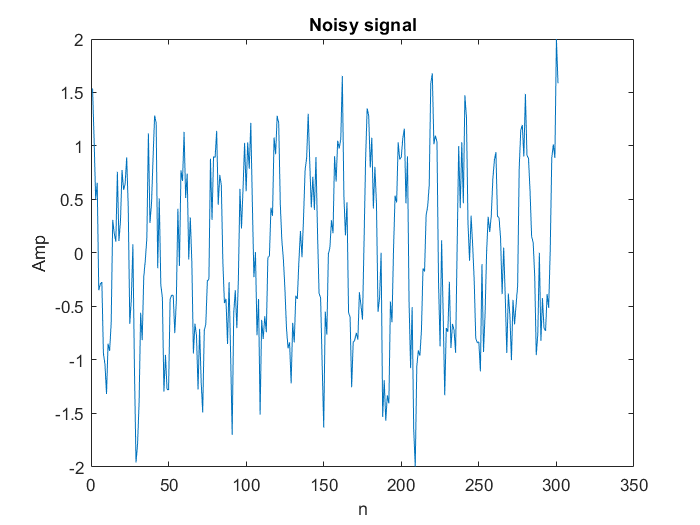

v=randn(1,301);
v=v/max(v); %Normalization
signal=cos(2*pi*(500/10000)*N);
x= signal + v; %defining x[n]


out=zeros(1,length(x));
R=0.8;
a1=-2*R*cos(2*pi*(500/10000));
a2=R^2;
G = (1 - R).*(1 - 2*R*cos(2*w0) + R^2)^0.5;

for k=1:length(x)
    if (k==1)
        out(1)=G*x(1);
        w1=out(1);
    
    elseif(k==2)
         out(2)=-a1*w1+G*x(2);
         w2=w1;
         w1=out(2);
    else
         out(k) = -a1*w1 - a2*w2 + G*x(k) ;
         w2 = w1;
         w1 = out(k);
    end
end

  
figure
plot(N,x)
xlabel('n');
ylabel('Amp');
title('Noisy signal')

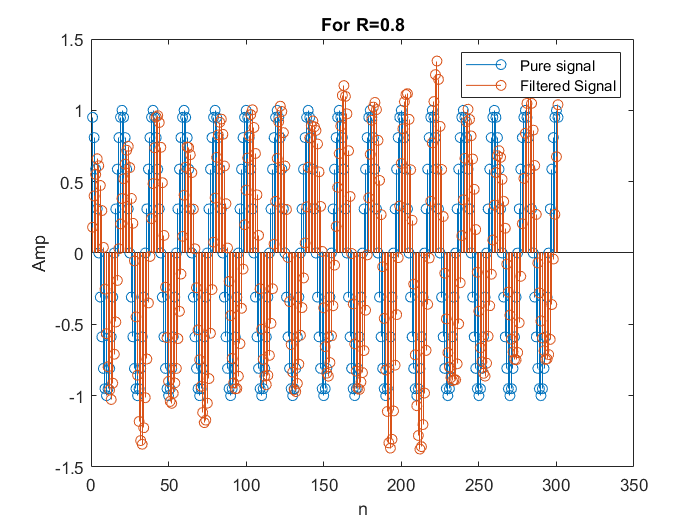


figure
stem(N,signal);
hold on
stem(N,out)
xlabel('n');
ylabel('Amp');
title('For R=0.8')
legend('Pure signal','Filtered Signal')

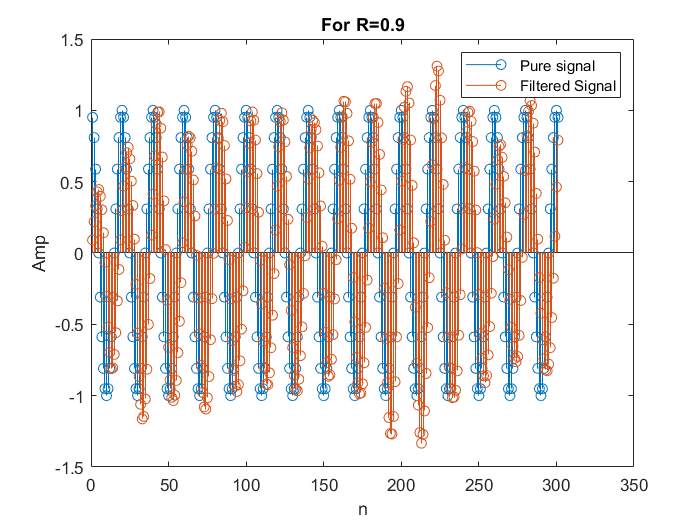

out2=zeros(1,length(x));
R=0.9;
a1=-2*R*cos(2*pi*(500/10000));
a2=R^2;
G = (1 - R).*(1 - 2*R*cos(2*w0) + R^2)^0.5;

for k=1:length(x)
    if (k==1)
        out2(1)=G*x(1);
        w1=out2(1);
    
    elseif(k==2)
         out2(2)=-a1*w1+G*x(2);
         w2=w1;
         w1=out2(2);
    else
         out2(k) = -a1*w1 - a2*w2 + G*x(k) ;
         w2 = w1;
         w1 = out2(k);
    end
end

figure
stem(N,signal);
hold on
stem(N,out2)
xlabel('n');
ylabel('Amp');
title('For R=0.9')
legend('Pure signal','Filtered Signal')

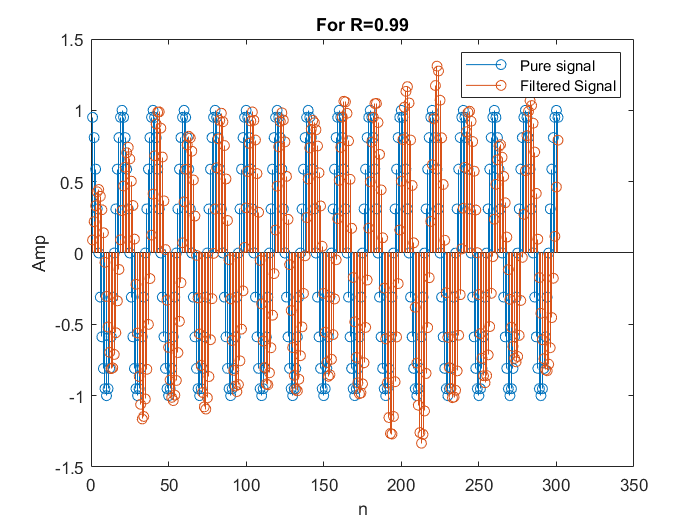


out3=zeros(1,length(x));
R=0.9;
a1=-2*R*cos(2*pi*(500/10000));
a2=R^2;
G = (1 - R).*(1 - 2*R*cos(2*w0) + R^2)^0.5;

for k=1:length(x)
    if (k==1)
        out3(1)=G*x(1);
        w1=out3(1);
    
    elseif(k==2)
         out3(2)=-a1*w1+G*x(2);
         w2=w1;
         w1=out3(2);
    else
         out3(k) = -a1*w1 - a2*w2 + G*x(k) ;
         w2 = w1;
         w1 = out3(k);
    end
end

figure
stem(N,signal);
hold on
stem(N,out3)
xlabel('n');
ylabel('Amp');
title('For R=0.99')
legend('Pure signal','Filtered Signal')

# 3-1-d

 Now we only pass the noise signal through the filter

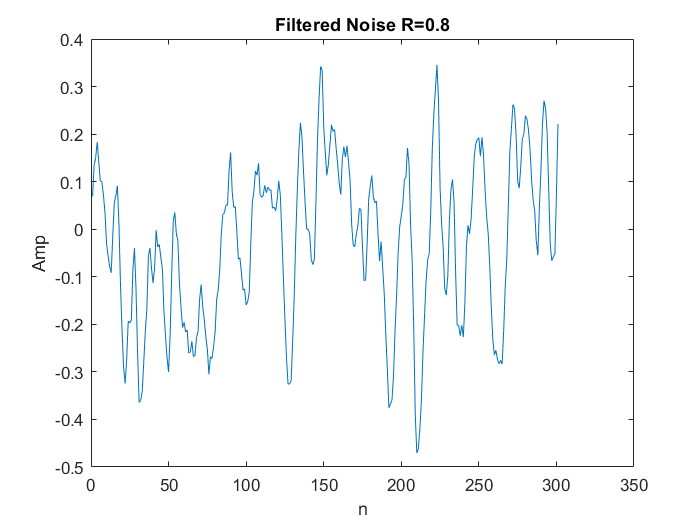

y_v=zeros(1,length(v));
R=0.8;
a1=-2*R*cos(2*pi*(500/10000));
a2=R^2;
G = (1 - R).*(1 - 2*R*cos(2*w0) + R^2)^0.5;

for k=1:length(v)
    if (k==1)
        y_v(1)=G*v(1);
        w1=y_v(1);
    
    elseif(k==2)
         y_v(2)=-a1*w1+G*v(2);
         w2=w1;
         w1=y_v(2);
    else
         y_v(k) = -a1*w1 - a2*w2 + G*v(k) ;
         w2 = w1;
         w1 = y_v(k);
    end
end

figure
plot(N,y_v);
xlabel('n');
ylabel('Amp');
title('Filtered Noise R=0.8')

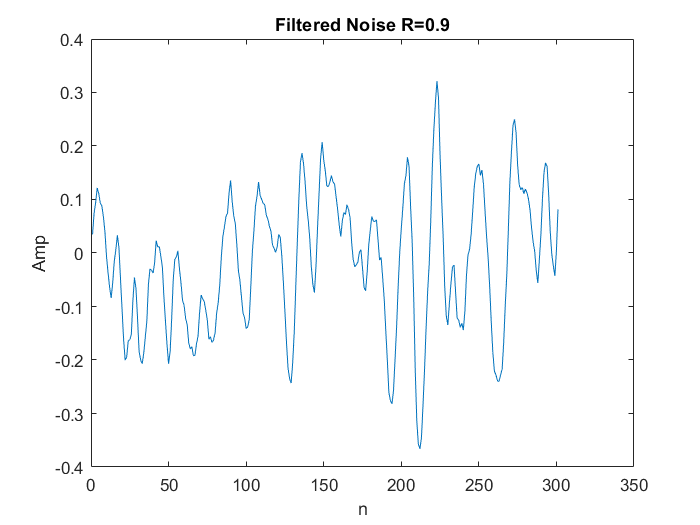

y_v=zeros(1,length(v));
R=0.9;
a1=-2*R*cos(2*pi*(500/10000));
a2=R^2;
G = (1 - R).*(1 - 2*R*cos(2*w0) + R^2)^0.5;

for k=1:length(v)
    if (k==1)
        y_v(1)=G*v(1);
        w1=y_v(1);
    
    elseif(k==2)
         y_v(2)=-a1*w1+G*v(2);
         w2=w1;
         w1=y_v(2);
    else
         y_v(k) = -a1*w1 - a2*w2 + G*v(k) ;
         w2 = w1;
         w1 = y_v(k);
    end
end

figure
plot(N,y_v);
xlabel('n');
ylabel('Amp');
title('Filtered Noise R=0.9')

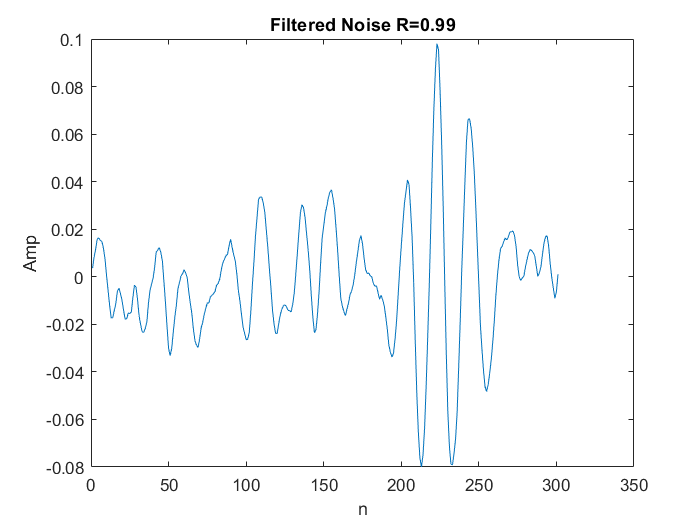

y_v=zeros(1,length(v));
R=0.99;
a1=-2*R*cos(2*pi*(500/10000));
a2=R^2;
G = (1 - R).*(1 - 2*R*cos(2*w0) + R^2)^0.5;

for k=1:length(v)
    if (k==1)
        y_v(1)=G*v(1);
        w1=y_v(1);
    
    elseif(k==2)
         y_v(2)=-a1*w1+G*v(2);
         w2=w1;
         w1=y_v(2);
    else
         y_v(k) = -a1*w1 - a2*w2 + G*v(k) ;
         w2 = w1;
         w1 = y_v(k);
    end
end

figure
plot(N,y_v);
xlabel('n');
ylabel('Amp');
title('Filtered Noise R=0.99')

### A bandpass filter allows a specific range of frequencies to pass through while attenuating frequencies outside that range. In the case of a recursive filter with the given coefficients (a1 and a2), the filter's frequency response will have a peak or resonance at a particular frequency range.

# 3-1-e

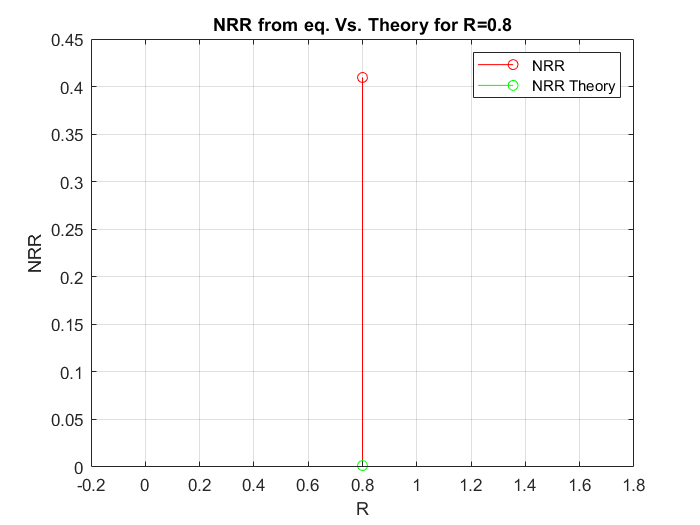

clc;
clear;

f0 = 500; 
fs = 10000; 
w  = 2 * pi * f0 / fs;
R = 0.8;
N = 300;
n  = 0:1:N;
s  = cos (w*n);
v  = randn(1,length(n));
x  = s + v;
w0=2 * pi * f0 / fs;


a1=-2*R*cos(2*pi*(500/10000));
a2=R^2;
G = (1 - R).*(1 - 2*R*cos(2*w0) + R^2)^0.5;
y_v = zeros(1,N);

for k = 1:N
        if (k == 1)
            y_v(k) = G*v(k) ;
            w1 = y_v(1) ;
        elseif(k == 2)
            y_v(k) = -a1*w1 + G*v(k) ;
            w2 = w1;
            w1 = y_v(2) ;
        else
            y_v(k) = -a1*w1 - a2*w2 + G*v(k) ;
            w2 = w1;
            w1 = y_v(k);
        end
end
    NRR = std(y_v)/std(v);
    NRR_th = (G^2/2*sin(w)^2)*((1/(1-R^2))-((cos(2*w)-R^2)/(1-2*R^2*cos(2*w)+R^4)));

    figure(10);
    stem(R, NRR, 'r');
    hold on;
    stem(R, NRR_th, 'g');
    grid on;
    xlabel('R');
    ylabel('NRR');
    title('NRR from eq. Vs. Theory for R=0.8');
    legend('NRR', 'NRR Theory');

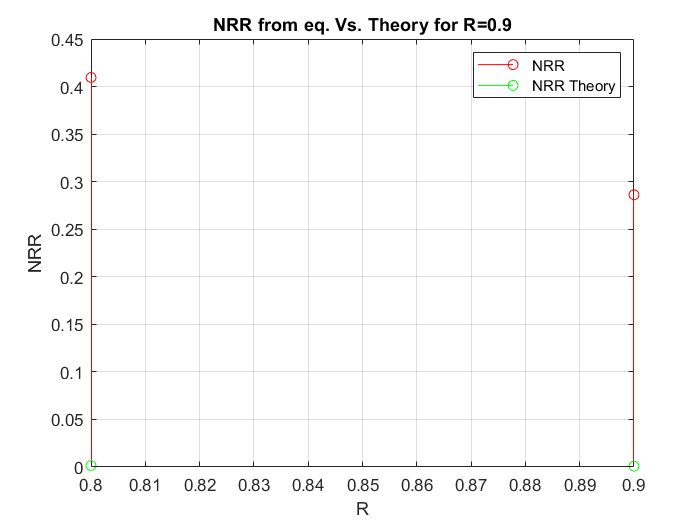

clc;
clear;

f0 = 500; 
fs = 10000; 
w  = 2 * pi * f0 / fs;
R = 0.9;
N = 300;
n  = 0:1:N;
s  = cos (w*n);
v  = randn(1,length(n));
x  = s + v;
w0=2 * pi * f0 / fs;


a1=-2*R*cos(2*pi*(500/10000));
a2=R^2;
G = (1 - R).*(1 - 2*R*cos(2*w0) + R^2)^0.5;
y_v = zeros(1,N);

for k = 1:N
        if (k == 1)
            y_v(k) = G*v(k) ;
            w1 = y_v(1) ;
        elseif(k == 2)
            y_v(k) = -a1*w1 + G*v(k) ;
            w2 = w1;
            w1 = y_v(2) ;
        else
            y_v(k) = -a1*w1 - a2*w2 + G*v(k) ;
            w2 = w1;
            w1 = y_v(k);
        end
end
    NRR = std(y_v)/std(v);
    NRR_th = (G^2/2*sin(w)^2)*((1/(1-R^2))-((cos(2*w)-R^2)/(1-2*R^2*cos(2*w)+R^4)));

    figure(10);
    stem(R, NRR, 'r');
    hold on;
    stem(R, NRR_th, 'g');
    grid on;
    xlabel('R');
    ylabel('NRR');
    title('NRR from eq. Vs. Theory for R=0.9');
    legend('NRR', 'NRR Theory');

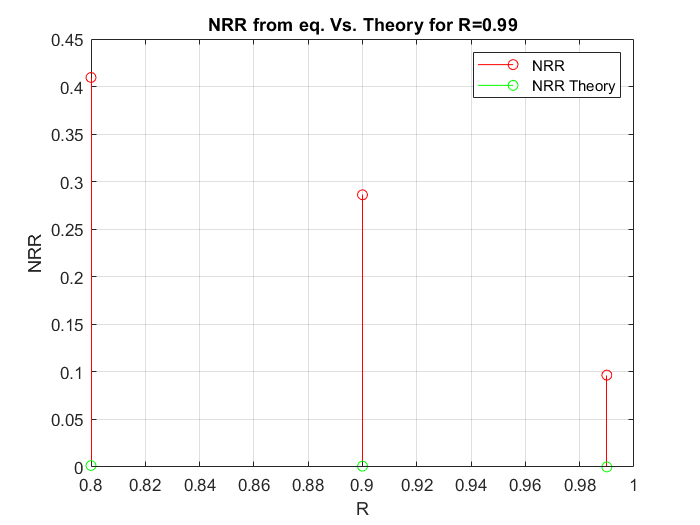



f0 = 500; 
fs = 10000; 
w  = 2 * pi * f0 / fs;
R = 0.99;
N = 300;
n  = 0:1:N;
s  = cos (w*n);
v  = randn(1,length(n));
x  = s + v;
w0=2 * pi * f0 / fs;


a1=-2*R*cos(2*pi*(500/10000));
a2=R^2;
G = (1 - R).*(1 - 2*R*cos(2*w0) + R^2)^0.5;
y_v = zeros(1,N);

for k = 1:N
        if (k == 1)
            y_v(k) = G*v(k) ;
            w1 = y_v(1) ;
        elseif(k == 2)
            y_v(k) = -a1*w1 + G*v(k) ;
            w2 = w1;
            w1 = y_v(2) ;
        else
            y_v(k) = -a1*w1 - a2*w2 + G*v(k) ;
            w2 = w1;
            w1 = y_v(k);
        end
end
    NRR = std(y_v)/std(v);
    NRR_th = (G^2/2*sin(w)^2)*((1/(1-R^2))-((cos(2*w)-R^2)/(1-2*R^2*cos(2*w)+R^4)));

    figure(10);
    stem(R, NRR, 'r');
    hold on;
    stem(R, NRR_th, 'g');
    grid on;
    xlabel('R');
    ylabel('NRR');
    title('NRR from eq. Vs. Theory for R=0.99');
    legend('NRR', 'NRR Theory');